%% Frequency sweep with 5 methods – includes HRV metrics (MeanRR, SDNN, RMSSD)
clear; close all; clc;
warning('off', 'MATLAB:colon:operandsNotLogicalScalar');
% -------------------------------------------------------------------------
% Choose database: 'mitdb', 'qtdb', or 'nstdb'
% -------------------------------------------------------------------------
database = 'mitdb';

% -------------------------------------------------------------------------
% Database-specific parameters
% -------------------------------------------------------------------------
if strcmp(database, 'mitdb')
    dataDir   = 'mitdb-mat';
    cacheFile = 'allData_mitdb.mat';
    Fs_orig_native = 360;          % original sampling rate (for reference)
    records = {'100','101','102','103','104','105','106','107','108','109', ...
        '111','112','113','114','115','116','117','118','119','121', ...
        '122','123','124','200','201','202','203','205','207','208', ...
        '209','210','212','213','214','215','217','219','220','221', ...
        '222','223','228','230','231','232','233','234'};
    % For MITDB we do NOT resample; use Fs_orig = Fs_orig_native
    Fs_orig = Fs_orig_native;
    resample_to_240 = false;

elseif strcmp(database, 'qtdb')
    dataDir   = 'qtdb-mat';
    cacheFile = 'allData_qtdb.mat';
    Fs_orig_native = 250;          % original QTDB sampling rate (for reference)
    Fs_target_resampled = 240;     % we will resample to this rate for processing
    records = { ...
        'sel30','sel31','sel32','sel33','sel34','sel35','sel36','sel37','sel38','sel39', ...
        'sel40','sel41','sel42','sel43','sel44','sel45','sel46','sel47','sel48','sel49', ...
        'sel50','sel51','sel52','sel100','sel102','sel103','sel104','sel114','sel116','sel117', ...
        'sel123','sel213','sel221','sel223','sel230','sel231','sel232','sel233','sel301','sel302', ...
        'sel306','sel307','sel308','sel310','sel803','sel808','sel811','sel820','sel821','sel840', ...
        'sel847','sel853','sel871','sel872','sel873','sel883','sel891','sel14046','sel14157','sel14172', ...
        'sel15814','sel16265','sel16272','sel16273','sel16420','sel16483','sel16539','sel16773','sel16786', ...
        'sel16795','sel17152','sel17453','sele0104','sele0106','sele0107','sele0110','sele0111','sele0112', ...
        'sele0114','sele0116','sele0121','sele0122','sele0124','sele0126','sele0129','sele0133','sele0136', ...
        'sele0166','sele0170','sele0203','sele0210','sele0211','sele0303','sele0405','sele0406','sele0409', ...
        'sele0411','sele0509','sele0603','sele0604','sele0606','sele0607','sele0609','sele0612','sele0704' };
    % For QTDB we will resample to 240 Hz and use that as the processing basis
    resample_to_240 = true;
    Fs_orig = Fs_target_resampled;   % the rate used for all sparse methods
elseif strcmp(database, 'nstdb')
    dataDir   = 'nstdb-mat';            % directory where Python script saved the .txt files
    cacheFile = 'allData_nstdb.mat';
    Fs_orig_native = 360;               % NSTDB is derived from MITDB records 118/119 (360 Hz)
    records = { ...
        '118e00','118e06','118e12','118e18','118e24','118e_6', ...
        '119e00','119e06','119e12','119e18','119e24','119e_6' };
    % No resampling needed for NSTDB – use native 360 Hz
    resample_to_240 = false;
    Fs_orig = Fs_orig_native;
else
    error('Unknown database. Choose ''mitdb'' or ''qtdb''.');
end

% -------------------------------------------------------------------------
% Common parameters (some derived from Fs_orig after possible resampling)
% -------------------------------------------------------------------------
Fs_pt       = 45;                   % fixed detection frequency for upsampled cases

% Target frequencies: divisors of Fs_orig (which is 240 for QTDB after resampling)
%divisors = [2,3,4,5,6,8,10,12,15,20,24,30];
divisors = [15,24];
target_list = Fs_orig ./ divisors;  % e.g., 240Hz → [120,80,60,48,40,30,24,20,16]

reconMethod = 'makima';
lowcut      = 5;
highcut     = 30;
filterOrder = 1;
tol_ms      = 150;                  % tolerance in milliseconds (applies to native time)

% Tolerance in samples at the native rate (250 for QTDB) – used for matching
tol_samples_native = round(tol_ms / 1000 * Fs_orig_native);

nRec = length(records);
% For per-record F1 and timing error
f1_native_perrec = zeros(nRec, 1);
err_native_perrec = zeros(nRec, 1);
% For per-record F1 for each target (rows=records, cols=targets)
f1_sparse_perrec = zeros(nRec, length(target_list));
err_sparse_perrec = zeros(nRec, length(target_list));

% -------------------------------------------------------------------------
% Load cached data (separate for each database)
% -------------------------------------------------------------------------
if exist(cacheFile, 'file')
    fprintf('Loading cached data from %s...\n', cacheFile);
    load(cacheFile, 'all_ecg', 'all_gt');
else
    fprintf('Cached data not found. Reading raw text files...\n');
    all_ecg = cell(nRec, 1);
    all_gt  = cell(nRec, 1);
    for i = 1:nRec
        rec = records{i};
        sigFile = fullfile(dataDir, [rec, '.txt']);
        annFile = fullfile(dataDir, [rec, '-ann.txt']);
        if ~exist(sigFile, 'file') || ~exist(annFile, 'file')
            error('Missing file for record %s', rec);
        end
        all_ecg{i} = load(sigFile); all_ecg{i} = all_ecg{i}(:);
        all_gt{i}  = load(annFile); all_gt{i}  = all_gt{i}(:);
    end
    save(cacheFile, 'all_ecg', 'all_gt');
    fprintf('Saved cached data to %s\n', cacheFile);
end

Loading cached data from allData_mitdb.mat...




% -------------------------------------------------------------------------
% If resampling to 240 Hz for QTDB, create resampled versions of ECG and GT
% -------------------------------------------------------------------------
if resample_to_240
    fprintf('Resampling QTDB from %d Hz to %d Hz for sparse processing...\n', ...
        Fs_orig_native, Fs_orig);
    all_ecg_resampled = cell(nRec,1);
    % Ground truth at 240 Hz (only needed for potential internal checks, but we will not use it for final metrics)
    % We keep the original 250 Hz GT for evaluation.
    for i = 1:nRec
        % Resample ECG using anti-aliasing filter
        ecg_240 = resample(all_ecg{i}, Fs_orig, Fs_orig_native);
        all_ecg_resampled{i} = ecg_240;
        if mod(i,20)==0; fprintf('  Resampled %d/%d records\n', i, nRec); end
    end
    % Replace original ECG with resampled version for all subsequent processing
    all_ecg = all_ecg_resampled;
    % Ground truth annotations remain at original 250 Hz
end

% -------------------------------------------------------------------------
% Bandpass filter design (depends on Fs_orig, i.e., 240 for QTDB after resampling)
% -------------------------------------------------------------------------
nyquist = Fs_orig / 2;
[b_bp, a_bp] = butter(filterOrder, [lowcut, highcut] / nyquist, 'bandpass');

% -------------------------------------------------------------------------
% 1. Original detection at NATIVE rate (250 Hz for QTDB, 360 for MITDB)
%    This serves as the reference baseline.
% -------------------------------------------------------------------------
fprintf('Computing original detection at native %d Hz (reference baseline)...\n', Fs_orig_native);

Computing original detection at native 360 Hz (reference baseline)...


total_tp_orig = 0; total_fp_orig = 0; total_fn_orig = 0;
orig_errors_ms = [];
time_orig_total = 0;

orig_RR_err = []; orig_SDNN_err = []; orig_RMSSD_err = [];

% We need the native ECG (not resampled) for baseline. For MITDB it's the same as all_ecg.
% For QTDB, we have to re-load or keep the original 250 Hz ECG separately.
if resample_to_240
    % Reload original 250 Hz ECG from cache
    fprintf('Reloading native 250 Hz ECG for baseline detection...\n');
    temp = load(cacheFile, 'all_ecg', 'all_gt');
    all_ecg_native = temp.all_ecg;
    all_gt_native  = temp.all_gt;   % same as original all_gt
else
    all_ecg_native = all_ecg;
    all_gt_native  = all_gt;
end

filtered_ecg_native = cell(nRec,1);

for i = 1:nRec
    ecg_raw_native = all_ecg_native{i};
    gt_native = all_gt_native{i};

    tic;
    obj_orig = BioSigKit(ecg_raw_native, Fs_orig_native, 0);
    obj_orig.PanTompkins;
    det_orig_native = sort(obj_orig.Results.R(:));
    [tp, fp, fn, err] = match_detections_with_errors(det_orig_native, gt_native, tol_samples_native, Fs_orig_native);
    % Per-record metrics for native
    sens_rec = tp/(tp+fn)*100;
    prec_rec = tp/(tp+fp)*100;
    f1_rec = 2*sens_rec*prec_rec/(sens_rec+prec_rec);
    f1_native_perrec(i) = f1_rec;

    err_native_perrec(i) = mean(err);   % mean timing error for this record
    time_orig_total = time_orig_total + toc;
    total_tp_orig = total_tp_orig + tp;
    total_fp_orig = total_fp_orig + fp;
    total_fn_orig = total_fn_orig + fn;
    orig_errors_ms = [orig_errors_ms; err];

    % HRV for original native
    [rr_err, sdnn_err, rmssd_err] = compute_hrv_errors(det_orig_native, gt_native, Fs_orig_native, tol_samples_native);
    if ~isempty(rr_err)
        orig_RR_err = [orig_RR_err; rr_err];
        orig_SDNN_err = [orig_SDNN_err; sdnn_err];
        orig_RMSSD_err = [orig_RMSSD_err; rmssd_err];
    end

    % Filtered version at native rate
    nyq_native = Fs_orig_native/2;
    [b_bp_native, a_bp_native] = butter(filterOrder, [lowcut, highcut]/nyq_native, 'bandpass');
    filtered_ecg_native{i} = filtfilt(b_bp_native, a_bp_native, ecg_raw_native);

    if mod(i,10)==0; fprintf('  Processed %d/%d records\n', i, nRec); end
end

  Processed 10/48 records
  Processed 20/48 records
  Processed 30/48 records
  Processed 40/48 records



sens_orig = total_tp_orig/(total_tp_orig+total_fn_orig)*100;
prec_orig = total_tp_orig/(total_tp_orig+total_fp_orig)*100;
f1_orig = 2*sens_orig*prec_orig/(sens_orig+prec_orig);
err_orig_mean = mean(orig_errors_ms);
err_orig_std = std(orig_errors_ms);
avg_time_orig = time_orig_total / nRec;

fprintf('Native %d Hz baseline: F1 = %.2f%%, Sens = %.2f%%, Prec = %.2f%%, Timing error = %.3f±%.3f ms, Time = %.4f s/record\n', ...
    Fs_orig_native, f1_orig, sens_orig, prec_orig, err_orig_mean, err_orig_std, avg_time_orig);

Native 360 Hz baseline: F1 = 99.19%, Sens = 99.17%, Prec = 99.20%, Timing error = -2.619±12.104 ms, Time = 0.5556 s/record


fprintf('Native HRV errors (self‑comparison, should be near zero): MeanRR = %.3f±%.3f ms, SDNN = %.3f±%.3f ms, RMSSD = %.3f±%.3f ms\n', ...
    mean(orig_RR_err), std(orig_RR_err), mean(orig_SDNN_err), std(orig_SDNN_err), mean(orig_RMSSD_err), std(orig_RMSSD_err));

Native HRV errors (self‑comparison, should be near zero): MeanRR = 0.155±1.788 ms, SDNN = 0.927±4.262 ms, RMSSD = 1.814±8.602 ms


% -------------------------------------------------------------------------
% Print per‑record native (360 Hz) detection stats
% -------------------------------------------------------------------------
fprintf('\n===== Per‑record native 360 Hz detection =====\n');


===== Per‑record native 360 Hz detection =====


fprintf('%-10s | %-8s | %-10s | %-10s | %-10s | %-10s | %-10s\n', ...
    'Record', 'F1(%)', 'TimingErr(ms)', 'ΔMeanRR(ms)', 'ΔSDNN(ms)', 'ΔRMSSD(ms)');

Record     | F1(%)    | TimingErr(ms) | ΔMeanRR(ms) | ΔSDNN(ms)  | ΔRMSSD(ms) | 

fprintf('----------|----------|------------|------------|------------|------------\n');

----------|----------|------------|------------|------------|------------


for i = 1:nRec
    fprintf('%-10s | %8.2f | %10.2f | %10.2f | %10.2f | %10.2f\n', ...
        records{i}, f1_native_perrec(i), err_native_perrec(i), ...
        orig_RR_err(i), orig_SDNN_err(i), orig_RMSSD_err(i));
end

100        |   100.00 |       0.19 |      -0.00 |       0.36 |       0.85
101        |    99.81 |       1.54 |      -0.00 |      -0.03 |      -0.15
102        |   100.00 |      11.71 |       0.01 |       3.04 |       6.79
103        |    99.98 |      -0.11 |      -0.00 |       0.01 |       0.04
104        |    98.68 |       1.70 |       0.06 |       0.50 |       0.81
105        |    99.05 |       0.84 |      -0.14 |       0.85 |       1.64
106        |    99.90 |      -1.04 |       1.36 |       1.25 |       0.65
107        |    99.62 |       7.33 |      -0.00 |      -0.26 |      -0.59
108        |    91.05 |     -20.99 |      -0.23 |       2.89 |       8.51
109        |    99.90 |      -1.29 |       0.00 |       0.77 |       1.95
111        |    99.74 |      -4.71 |       0.01 |       0.47 |       1.06
112        |   100.00 |      -2.80 |       0.00 |      -0.03 |      -0.12
113        |   100.00 |      -0.85 |       0.00 |      -0.01 |       0.02
114        |    85.99 |     -13.44 |  

fprintf('================================================================\n');


% -------------------------------------------------------------------------
% For sparse methods, we need filtered ECG at the processing rate (Fs_orig)
% -------------------------------------------------------------------------
filtered_ecg = cell(nRec,1);
for i = 1:nRec
    ecg_raw = all_ecg{i};   % already resampled if resample_to_240 is true
    filtered_ecg{i} = filtfilt(b_bp, a_bp, ecg_raw);
end

% -------------------------------------------------------------------------
% Prepare storage for sweep results
% -------------------------------------------------------------------------
results = struct();

% ----- New storage for per‑record data -----
% Dimensions: nRec x length(target_list) x 4 (methods: 1=naive,2=maxhold,3=intel,4=adapt)
perrec_f1   = zeros(nRec, length(target_list), 4);
perrec_err  = zeros(nRec, length(target_list), 4);   % mean timing error per record (ms)
perrec_hrv  = zeros(nRec, length(target_list), 4, 3); % last dim: 1=ΔMeanRR,2=ΔSDNN,3=ΔRMSSD

% -------------------------------------------------------------------------
% Sweep over target frequencies (based on Fs_orig, e.g., 240 Hz)
% -------------------------------------------------------------------------
fprintf('\n================================================================================\n');

fprintf('Starting frequency sweep on %d Hz processed data (targets are divisors of %d)\n', Fs_orig, Fs_orig);

Starting frequency sweep on 360 Hz processed data (targets are divisors of 360)


fprintf('All detections will be mapped back to native %d Hz for comparison.\n', Fs_orig_native);

All detections will be mapped back to native 360 Hz for comparison.


fprintf('================================================================================\n');


for f_idx = 1:length(target_list)
    Fs_target = target_list(f_idx);
    use_upsampling = (Fs_target < 45);

    blockSize_naive = Fs_orig / Fs_target;
    blockSize_intel = 2 * blockSize_naive;

    if abs(blockSize_naive - round(blockSize_naive)) > 1e-6 || ...
            abs(blockSize_intel - round(blockSize_intel)) > 1e-6
        error('Block size not integer for Fs_target = %.2f Hz (Fs_orig = %d)', Fs_target, Fs_orig);
    end

    blockSize_naive = round(blockSize_naive);
    blockSize_intel = round(blockSize_intel);

    fprintf('\n--- Target frequency = %.2f Hz (blockSize = %d) ---\n', Fs_target, blockSize_naive);
    if use_upsampling
        Fs_detection = Fs_pt;
        fprintf('Upsampling to %d Hz via Makima, detection at %d Hz\n', Fs_pt, Fs_detection);
    else
        Fs_detection = Fs_target;
        fprintf('Direct sparse signal, detection at %d Hz\n', Fs_detection);
    end

    trim_start_s = 0.5;          % seconds to trim from start of reconstructed signal

    % Reset accumulators
    tp_naive = 0; fp_naive = 0; fn_naive = 0;
    tp_maxhold = 0; fp_maxhold = 0; fn_maxhold = 0;
    tp_intel = 0; fp_intel = 0; fn_intel = 0;
    tp_adapt = 0; fp_adapt = 0; fn_adapt = 0;

    err_naive = []; err_maxhold = []; err_intel = []; err_adapt = [];

    hrv_naive_RR = []; hrv_naive_SDNN = []; hrv_naive_RMSSD = [];
    hrv_maxhold_RR = []; hrv_maxhold_SDNN = []; hrv_maxhold_RMSSD = [];
    hrv_intel_RR = []; hrv_intel_SDNN = []; hrv_intel_RMSSD = [];
    hrv_adapt_RR = []; hrv_adapt_SDNN = []; hrv_adapt_RMSSD = [];

    time_naive_total = 0; time_maxhold_total = 0; time_intel_total = 0; time_adapt_total = 0;

    for i = 1:nRec
        ecg_bp = filtered_ecg{i};
        gt_native = all_gt_native{i};   % original 250 Hz annotations

        % -----------------------------------------------------------------
        % Methods using blockSize_naive (Naive, Max‑hold)
        % -----------------------------------------------------------------
        N_naive = floor(length(ecg_bp) / blockSize_naive) * blockSize_naive;
        ecg_bp_naive = ecg_bp(1:N_naive);
        numBlocks_naive = N_naive / blockSize_naive;
        if abs(numBlocks_naive - round(numBlocks_naive)) > 1e-6
            error('numBlocks_naive not integer for Fs_target = %.2f Hz', Fs_target);
        end
        numBlocks_naive = round(numBlocks_naive);
        block_offsets_naive = (0:numBlocks_naive-1) * blockSize_naive;

        % ----- Naive decimation -----
        t_method = tic;
        naive_idx = block_offsets_naive + 1;
        orig_idx_naive = naive_idx;   % indices in 240 Hz world
        sparse_val_naive = ecg_bp_naive(naive_idx);

        if use_upsampling
            sparse_time = (orig_idx_naive - 1) / Fs_orig;
            time_det = (0:1/Fs_detection:(N_naive-1)/Fs_orig)';
            recon_naive = interp1(sparse_time, sparse_val_naive, time_det, reconMethod);
            sparse_time_naive = sparse_time;
            sparse_idx_naive = orig_idx_naive;
        else
            recon_naive = sparse_val_naive;
        end

        % ----- Trim first 0.5 seconds -----
        trim_len = round(trim_start_s * Fs_detection);
        if trim_len < length(recon_naive)
            recon_naive_trim = recon_naive(trim_len+1:end);
            trim_offset = trim_len;
        else
            error('Trim length exceeds signal length for Naive');
        end
        obj = BioSigKit(recon_naive_trim, Fs_detection, 0);
        obj.PanTompkins;
        det_pt_trim = sort(obj.Results.R(:));
        det_pt = det_pt_trim + trim_offset;   % shift back to original timeline

        if use_upsampling
            det_240 = map_detections_to_original(det_pt, sparse_time_naive, sparse_idx_naive, Fs_detection, Fs_orig);
        else
            det_240 = orig_idx_naive(det_pt);
            det_240 = sort(det_240(:));
        end

        % Map 240 Hz detections to native 250 Hz indices (via time)
        det_native = round((det_240 - 1) / Fs_orig * Fs_orig_native) + 1;
        det_native = unique(det_native);

        [tp, fp, fn, err] = match_detections_with_errors(det_native, gt_native, tol_samples_native, Fs_orig_native);
        time_naive_total = time_naive_total + toc(t_method);
        tp_naive = tp_naive + tp; fp_naive = fp_naive + fp; fn_naive = fn_naive + fn;
        err_naive = [err_naive; err];

        % HRV
        [rr_e, sdnn_e, rmssd_e] = compute_hrv_errors(det_native, gt_native, Fs_orig_native, tol_samples_native);
        if ~isempty(rr_e)
            hrv_naive_RR = [hrv_naive_RR; rr_e];
            hrv_naive_SDNN = [hrv_naive_SDNN; sdnn_e];
            hrv_naive_RMSSD = [hrv_naive_RMSSD; rmssd_e];
        end
        % save
        sens = tp/(tp+fn)*100; prec = tp/(tp+fp)*100;
        perrec_f1(i, f_idx, 1) = 2*sens*prec/(sens+prec);
        perrec_err(i, f_idx, 1) = mean(err);
        if ~isempty(rr_e)
            perrec_hrv(i, f_idx, 1, :) = [rr_e, sdnn_e, rmssd_e];
        else
            perrec_hrv(i, f_idx, 1, :) = NaN;
        end

        % ----- Max‑hold -----
        t_method = tic;
        blocks_naive = reshape(ecg_bp_naive, blockSize_naive, numBlocks_naive);
        [~, max_abs_pos] = max(abs(blocks_naive), [], 1);
        maxhold_global = block_offsets_naive + max_abs_pos;
        orig_idx_maxhold = maxhold_global;
        sparse_val_maxhold = ecg_bp_naive(maxhold_global);

        if use_upsampling
            sparse_time = (orig_idx_maxhold - 1) / Fs_orig;
            time_det = (0:1/Fs_detection:(N_naive-1)/Fs_orig)';
            recon_maxhold = interp1(sparse_time, sparse_val_maxhold, time_det, reconMethod);
            sparse_time_maxhold = sparse_time;
            sparse_idx_maxhold = orig_idx_maxhold;
        else
            recon_maxhold = sparse_val_maxhold;
        end

        % ----- Trim first 0.5 seconds -----
        trim_len = round(trim_start_s * Fs_detection);
        if trim_len < length(recon_maxhold)
            recon_maxhold_trim = recon_maxhold(trim_len+1:end);
            trim_offset = trim_len;
        else
            error('Trim length exceeds signal length for Maxhold');
        end
        obj = BioSigKit(recon_maxhold_trim, Fs_detection, 0);
        obj.PanTompkins;
        det_pt_trim = sort(obj.Results.R(:));
        det_pt = det_pt_trim + trim_offset;

        if use_upsampling
            det_240 = map_detections_to_original(det_pt, sparse_time_maxhold, sparse_idx_maxhold, Fs_detection, Fs_orig);
        else
            det_240 = orig_idx_maxhold(det_pt);
            det_240 = sort(det_240(:));
        end

        det_native = round((det_240 - 1) / Fs_orig * Fs_orig_native) + 1;
        det_native = unique(det_native);

        [tp, fp, fn, err] = match_detections_with_errors(det_native, gt_native, tol_samples_native, Fs_orig_native);
        time_maxhold_total = time_maxhold_total + toc(t_method);
        tp_maxhold = tp_maxhold + tp; fp_maxhold = fp_maxhold + fp; fn_maxhold = fn_maxhold + fn;
        err_maxhold = [err_maxhold; err];

        [rr_e, sdnn_e, rmssd_e] = compute_hrv_errors(det_native, gt_native, Fs_orig_native, tol_samples_native);
        if ~isempty(rr_e)
            hrv_maxhold_RR = [hrv_maxhold_RR; rr_e];
            hrv_maxhold_SDNN = [hrv_maxhold_SDNN; sdnn_e];
            hrv_maxhold_RMSSD = [hrv_maxhold_RMSSD; rmssd_e];
        end
        % save
        sens = tp/(tp+fn)*100; prec = tp/(tp+fp)*100;
        perrec_f1(i, f_idx, 2) = 2*sens*prec/(sens+prec);
        perrec_err(i, f_idx, 2) = mean(err);
        if ~isempty(rr_e)
            perrec_hrv(i, f_idx, 2, :) = [rr_e, sdnn_e, rmssd_e];
        else
            perrec_hrv(i, f_idx, 2, :) = NaN;
        end

        % -----------------------------------------------------------------
        % Methods using blockSize_intel (Min+Max, Adaptive)
        % -----------------------------------------------------------------
        N_intel = floor(length(ecg_bp) / blockSize_intel) * blockSize_intel;
        ecg_bp_intel = ecg_bp(1:N_intel);
        numBlocks_intel = N_intel / blockSize_intel;
        if abs(numBlocks_intel - round(numBlocks_intel)) > 1e-6
            error('numBlocks_intel not integer for Fs_target = %.2f Hz', Fs_target);
        end
        numBlocks_intel = round(numBlocks_intel);
        block_offsets_intel = (0:numBlocks_intel-1) * blockSize_intel;

        % ----- Min+Max -----
        t_method = tic;
        blocks_intel = reshape(ecg_bp_intel, blockSize_intel, numBlocks_intel);
        [min_vals, min_pos] = min(blocks_intel, [], 1);
        [max_vals, max_pos] = max(blocks_intel, [], 1);
        min_global = block_offsets_intel + min_pos;
        max_global = block_offsets_intel + max_pos;
        sparse_idx_all = [min_global, max_global];
        sparse_val_all = [min_vals, max_vals];
        [sparse_idx, sortIdx] = sort(sparse_idx_all);
        sparse_val = sparse_val_all(sortIdx);
        [~, ia] = unique(sparse_idx, 'stable');
        sparse_idx = sparse_idx(ia);
        sparse_val = sparse_val(ia);
        orig_idx_intel = sparse_idx;

        if use_upsampling
            sparse_time = (orig_idx_intel - 1) / Fs_orig;
            time_det = (0:1/Fs_detection:(N_intel-1)/Fs_orig)';
            recon_intel = interp1(sparse_time, sparse_val, time_det, reconMethod);
            sparse_time_intel = sparse_time;
            sparse_idx_intel = orig_idx_intel;
        else
            recon_intel = sparse_val;
        end

        % ----- Trim first 0.5 seconds -----
        trim_len = round(trim_start_s * Fs_detection);
        if trim_len < length(recon_intel)
            recon_intel_trim = recon_intel(trim_len+1:end);
            trim_offset = trim_len;
        else
            error('Trim length exceeds signal length for Min+Max');
        end
        obj = BioSigKit(recon_intel_trim, Fs_detection, 0);
        obj.PanTompkins;
        det_pt_trim = sort(obj.Results.R(:));
        det_pt = det_pt_trim + trim_offset;

        if use_upsampling
            det_240 = map_detections_to_original(det_pt, sparse_time_intel, sparse_idx_intel, Fs_detection, Fs_orig);
        else
            det_240 = orig_idx_intel(det_pt);
            det_240 = sort(det_240(:));
        end

        det_native = round((det_240 - 1) / Fs_orig * Fs_orig_native) + 1;
        det_native = unique(det_native);

        [tp, fp, fn, err] = match_detections_with_errors(det_native, gt_native, tol_samples_native, Fs_orig_native);
        time_intel_total = time_intel_total + toc(t_method);

        % Compute per-record metrics for Min-Max using current record's values
        sens_intel_rec = tp/(tp+fn)*100;
        prec_intel_rec = tp/(tp+fp)*100;
        f1_intel_rec = 2*sens_intel_rec*prec_intel_rec/(sens_intel_rec+prec_intel_rec);

        f1_sparse_perrec(i, f_idx) = f1_intel_rec;
        err_sparse_perrec(i, f_idx) = mean(err);   % absolute error

        % Then accumulate totals
        tp_intel = tp_intel + tp;
        fp_intel = fp_intel + fp;
        fn_intel = fn_intel + fn;
        err_intel = [err_intel; err];

        [rr_e, sdnn_e, rmssd_e] = compute_hrv_errors(det_native, gt_native, Fs_orig_native, tol_samples_native);
        if ~isempty(rr_e)
            hrv_intel_RR = [hrv_intel_RR; rr_e];
            hrv_intel_SDNN = [hrv_intel_SDNN; sdnn_e];
            hrv_intel_RMSSD = [hrv_intel_RMSSD; rmssd_e];
        end

        % save
        sens = tp/(tp+fn)*100; prec = tp/(tp+fp)*100;
        perrec_f1(i, f_idx, 3) = 2*sens*prec/(sens+prec);
        perrec_err(i, f_idx, 3) = mean(err);
        if ~isempty(rr_e)
            perrec_hrv(i, f_idx, 3, :) = [rr_e, sdnn_e, rmssd_e];
        else
            perrec_hrv(i, f_idx, 3, :) = NaN;
        end

        % ----- Adaptive -----
        t_method = tic;
        d = diff(blocks_intel, 1, 1);
        signs = sign(d); signs(isnan(signs)) = 0;
        hasDirChange = any(diff(signs, 1, 1) ~= 0, 1);
        [min_vals, min_pos] = min(blocks_intel, [], 1);
        [max_vals, max_pos] = max(blocks_intel, [], 1);
        min_global = block_offsets_intel + min_pos;
        max_global = block_offsets_intel + max_pos;
        first_global = block_offsets_intel + 1;
        mid_pos = round(blockSize_intel/2);
        mid_global = block_offsets_intel + mid_pos;
        first_vals = blocks_intel(1, :);
        mid_vals = blocks_intel(mid_pos, :);

        sparse_idx_adapt = zeros(1, 2*numBlocks_intel);
        sparse_val_adapt = zeros(1, 2*numBlocks_intel);
        idx_change = find(hasDirChange);
        idx_nochange = find(~hasDirChange);
        if ~isempty(idx_change)
            change_idx = reshape([2*idx_change-1; 2*idx_change], 1, []);
            sparse_idx_adapt(change_idx) = [min_global(idx_change), max_global(idx_change)];
            sparse_val_adapt(change_idx) = [min_vals(idx_change), max_vals(idx_change)];
        end
        if ~isempty(idx_nochange)
            nochange_idx = reshape([2*idx_nochange-1; 2*idx_nochange], 1, []);
            sparse_idx_adapt(nochange_idx) = [first_global(idx_nochange), mid_global(idx_nochange)];
            sparse_val_adapt(nochange_idx) = [first_vals(idx_nochange), mid_vals(idx_nochange)];
        end
        [sparse_idx, sortIdx] = sort(sparse_idx_adapt);
        sparse_val = sparse_val_adapt(sortIdx);
        [~, ia] = unique(sparse_idx, 'stable');
        sparse_idx = sparse_idx(ia);
        sparse_val = sparse_val(ia);
        orig_idx_adapt = sparse_idx;

        if use_upsampling
            sparse_time = (orig_idx_adapt - 1) / Fs_orig;
            time_det = (0:1/Fs_detection:(N_intel-1)/Fs_orig)';
            recon_adapt = interp1(sparse_time, sparse_val, time_det, reconMethod);
            sparse_time_adapt = sparse_time;
            sparse_idx_adapt = orig_idx_adapt;
        else
            recon_adapt = sparse_val;
        end

        % ----- Trim first 0.5 seconds -----
        trim_len = round(trim_start_s * Fs_detection);
        if trim_len < length(recon_adapt)
            recon_adapt_trim = recon_adapt(trim_len+1:end);
            trim_offset = trim_len;
        else
            error('Trim length exceeds signal length for Adaptive');
        end
        obj = BioSigKit(recon_adapt_trim, Fs_detection, 0);
        obj.PanTompkins;
        det_pt_trim = sort(obj.Results.R(:));
        det_pt = det_pt_trim + trim_offset;

        if use_upsampling
            det_240 = map_detections_to_original(det_pt, sparse_time_adapt, sparse_idx_adapt, Fs_detection, Fs_orig);
        else
            det_240 = orig_idx_adapt(det_pt);
            det_240 = sort(det_240(:));
        end

        det_native = round((det_240 - 1) / Fs_orig * Fs_orig_native) + 1;
        det_native = unique(det_native);

        [tp, fp, fn, err] = match_detections_with_errors(det_native, gt_native, tol_samples_native, Fs_orig_native);
        time_adapt_total = time_adapt_total + toc(t_method);
        tp_adapt = tp_adapt + tp; fp_adapt = fp_adapt + fp; fn_adapt = fn_adapt + fn;
        err_adapt = [err_adapt; err];

        [rr_e, sdnn_e, rmssd_e] = compute_hrv_errors(det_native, gt_native, Fs_orig_native, tol_samples_native);
        if ~isempty(rr_e)
            hrv_adapt_RR = [hrv_adapt_RR; rr_e];
            hrv_adapt_SDNN = [hrv_adapt_SDNN; sdnn_e];
            hrv_adapt_RMSSD = [hrv_adapt_RMSSD; rmssd_e];
        end
        % save
        sens = tp/(tp+fn)*100; prec = tp/(tp+fp)*100;
        perrec_f1(i, f_idx, 4) = 2*sens*prec/(sens+prec);
        perrec_err(i, f_idx, 4) = mean(err);
        if ~isempty(rr_e)
            perrec_hrv(i, f_idx, 4, :) = [rr_e, sdnn_e, rmssd_e];
        else
            perrec_hrv(i, f_idx, 4, :) = NaN;
        end

        if mod(i,10)==0; fprintf('  Processed %d/%d records\n', i, nRec); end
    end

    % Compute metrics (identical to original)
    sens_naive = tp_naive/(tp_naive+fn_naive)*100;
    prec_naive = tp_naive/(tp_naive+fp_naive)*100;
    f1_naive = 2*sens_naive*prec_naive/(sens_naive+prec_naive);

    sens_maxhold = tp_maxhold/(tp_maxhold+fn_maxhold)*100;
    prec_maxhold = tp_maxhold/(tp_maxhold+fp_maxhold)*100;
    f1_maxhold = 2*sens_maxhold*prec_maxhold/(sens_maxhold+prec_maxhold);

    sens_intel = tp_intel/(tp_intel+fn_intel)*100;
    prec_intel = tp_intel/(tp_intel+fp_intel)*100;
    f1_intel = 2*sens_intel*prec_intel/(sens_intel+prec_intel);

    sens_adapt = tp_adapt/(tp_adapt+fn_adapt)*100;
    prec_adapt = tp_adapt/(tp_adapt+fp_adapt)*100;
    f1_adapt = 2*sens_adapt*prec_adapt/(sens_adapt+prec_adapt);

    err_naive_mean = mean(err_naive); err_naive_std = std(err_naive);
    err_maxhold_mean = mean(err_maxhold); err_maxhold_std = std(err_maxhold);
    err_intel_mean = mean(err_intel); err_intel_std = std(err_intel);
    err_adapt_mean = mean(err_adapt); err_adapt_std = std(err_adapt);

    avg_time_naive = time_naive_total / nRec;
    avg_time_maxhold = time_maxhold_total / nRec;
    avg_time_intel = time_intel_total / nRec;
    avg_time_adapt = time_adapt_total / nRec;

    % HRV summaries
    if isempty(hrv_naive_RR)
        hrv_naive_mean = [NaN, NaN, NaN]; hrv_naive_std = [NaN, NaN, NaN];
    else
        hrv_naive_mean = [mean(hrv_naive_RR), mean(hrv_naive_SDNN), mean(hrv_naive_RMSSD)];
        hrv_naive_std  = [std(hrv_naive_RR), std(hrv_naive_SDNN), std(hrv_naive_RMSSD)];
    end
    if isempty(hrv_maxhold_RR)
        hrv_maxhold_mean = [NaN, NaN, NaN]; hrv_maxhold_std = [NaN, NaN, NaN];
    else
        hrv_maxhold_mean = [mean(hrv_maxhold_RR), mean(hrv_maxhold_SDNN), mean(hrv_maxhold_RMSSD)];
        hrv_maxhold_std  = [std(hrv_maxhold_RR), std(hrv_maxhold_SDNN), std(hrv_maxhold_RMSSD)];
    end
    if isempty(hrv_intel_RR)
        hrv_intel_mean = [NaN, NaN, NaN]; hrv_intel_std = [NaN, NaN, NaN];
    else
        hrv_intel_mean = [mean(hrv_intel_RR), mean(hrv_intel_SDNN), mean(hrv_intel_RMSSD)];
        hrv_intel_std  = [std(hrv_intel_RR), std(hrv_intel_SDNN), std(hrv_intel_RMSSD)];
    end
    if isempty(hrv_adapt_RR)
        hrv_adapt_mean = [NaN, NaN, NaN]; hrv_adapt_std = [NaN, NaN, NaN];
    else
        hrv_adapt_mean = [mean(hrv_adapt_RR), mean(hrv_adapt_SDNN), mean(hrv_adapt_RMSSD)];
        hrv_adapt_std  = [std(hrv_adapt_RR), std(hrv_adapt_SDNN), std(hrv_adapt_RMSSD)];
    end

    % Store results (same structure as before)
    results(f_idx).Fs_target = Fs_target;
    results(f_idx).use_upsampling = use_upsampling;
    results(f_idx).naive = struct('TP', tp_naive, 'FP', fp_naive, 'FN', fn_naive, ...
        'F1', f1_naive, 'Sens', sens_naive, 'Prec', prec_naive, ...
        'ErrMean', err_naive_mean, 'ErrStd', err_naive_std, ...
        'Time', avg_time_naive, ...
        'HRV_MeanRR', hrv_naive_mean(1), 'HRV_SDNN', hrv_naive_mean(2), 'HRV_RMSSD', hrv_naive_mean(3), ...
        'HRV_MeanRR_std', hrv_naive_std(1), 'HRV_SDNN_std', hrv_naive_std(2), 'HRV_RMSSD_std', hrv_naive_std(3));
    results(f_idx).maxhold = struct('TP', tp_maxhold, 'FP', fp_maxhold, 'FN', fn_maxhold, ...
        'F1', f1_maxhold, 'Sens', sens_maxhold, 'Prec', prec_maxhold, ...
        'ErrMean', err_maxhold_mean, 'ErrStd', err_maxhold_std, ...
        'Time', avg_time_maxhold, ...
        'HRV_MeanRR', hrv_maxhold_mean(1), 'HRV_SDNN', hrv_maxhold_mean(2), 'HRV_RMSSD', hrv_maxhold_mean(3), ...
        'HRV_MeanRR_std', hrv_maxhold_std(1), 'HRV_SDNN_std', hrv_maxhold_std(2), 'HRV_RMSSD_std', hrv_maxhold_std(3));
    results(f_idx).intel = struct('TP', tp_intel, 'FP', fp_intel, 'FN', fn_intel, ...
        'F1', f1_intel, 'Sens', sens_intel, 'Prec', prec_intel, ...
        'ErrMean', err_intel_mean, 'ErrStd', err_intel_std, ...
        'Time', avg_time_intel, ...
        'HRV_MeanRR', hrv_intel_mean(1), 'HRV_SDNN', hrv_intel_mean(2), 'HRV_RMSSD', hrv_intel_mean(3), ...
        'HRV_MeanRR_std', hrv_intel_std(1), 'HRV_SDNN_std', hrv_intel_std(2), 'HRV_RMSSD_std', hrv_intel_std(3));
    results(f_idx).adapt = struct('TP', tp_adapt, 'FP', fp_adapt, 'FN', fn_adapt, ...
        'F1', f1_adapt, 'Sens', sens_adapt, 'Prec', prec_adapt, ...
        'ErrMean', err_adapt_mean, 'ErrStd', err_adapt_std, ...
        'Time', avg_time_adapt, ...
        'HRV_MeanRR', hrv_adapt_mean(1), 'HRV_SDNN', hrv_adapt_mean(2), 'HRV_RMSSD', hrv_adapt_mean(3), ...
        'HRV_MeanRR_std', hrv_adapt_std(1), 'HRV_SDNN_std', hrv_adapt_std(2), 'HRV_RMSSD_std', hrv_adapt_std(3));
end


--- Target frequency = 24.00 Hz (blockSize = 15) ---


Upsampling to 45 Hz via Makima, detection at 45 Hz


  Processed 10/48 records
  Processed 20/48 records
  Processed 30/48 records
  Processed 40/48 records



--- Target frequency = 15.00 Hz (blockSize = 24) ---


Upsampling to 45 Hz via Makima, detection at 45 Hz


  Processed 10/48 records
  Processed 20/48 records
  Processed 30/48 records
  Processed 40/48 records



% -------------------------------------------------------------------------
% Export per‑record results to CSV (one row per record per target per method)
% -------------------------------------------------------------------------
numRows = 1 + nRec * length(target_list) * 4;  % header + data rows
csvData = cell(numRows, 8);  % 8 columns

% Header row
csvData(1,:) = {'Record', 'Target_Hz', 'Method', 'F1_percent', 'TimingErr_ms', ...
    'DeltaMeanRR_ms', 'DeltaSDNN_ms', 'DeltaRMSSD_ms'};

methodNames = {'Naive','Maxhold','MinMax','Adaptive'};

rowIdx = 2;
for i = 1:nRec
    recName = records{i};
    for f_idx = 1:length(target_list)
        Fs_targ = target_list(f_idx);
        for m = 1:4
            f1_val = perrec_f1(i, f_idx, m);
            err_val = perrec_err(i, f_idx, m);
            hr = squeeze(perrec_hrv(i, f_idx, m, :));   % 3-element column vector
            csvData(rowIdx, :) = {recName, Fs_targ, methodNames{m}, f1_val, err_val, ...
                hr(1), hr(2), hr(3)};
            rowIdx = rowIdx + 1;
        end
    end
end

% Write to CSV file
writecell(csvData, sprintf('per_record_results_%s.csv', database));
fprintf('Saved per‑record results to per_record_results_%s.csv\n', database);

Saved per‑record results to per_record_results_mitdb.csv


% -------------------------------------------------------------------------
% Print per‑record Min+Max results for selected frequencies
% -------------------------------------------------------------------------
target_interest = [30, 24];
fprintf('\n===== Per‑record Min+Max results (selected frequencies) =====\n');


===== Per‑record Min+Max results (selected frequencies) =====


for t = target_interest
    f_idx = find(abs(target_list - t) < 0.1);
    if isempty(f_idx); continue; end
    fprintf('\n--- %d Hz ---\n', t);
    for i = 1:nRec
        fprintf('%s: F1 = %.2f%%, timing err = %.2f ms, ΔRMSSD = %.2f ms\n', ...
            records{i}, perrec_f1(i, f_idx, 3), perrec_err(i, f_idx, 3), ...
            perrec_hrv(i, f_idx, 3, 3));
    end
end


--- 24 Hz ---


100: F1 = 99.96%, timing err = 0.34 ms, ΔRMSSD = 0.95 ms
101: F1 = 99.87%, timing err = -0.73 ms, ΔRMSSD = 1.01 ms
102: F1 = 99.93%, timing err = 2.91 ms, ΔRMSSD = 11.57 ms
103: F1 = 99.98%, timing err = 0.71 ms, ΔRMSSD = 0.90 ms
104: F1 = 99.06%, timing err = -2.52 ms, ΔRMSSD = 1.77 ms
105: F1 = 99.07%, timing err = -0.42 ms, ΔRMSSD = 1.80 ms
106: F1 = 99.85%, timing err = 0.21 ms, ΔRMSSD = -0.73 ms
107: F1 = 99.91%, timing err = -0.23 ms, ΔRMSSD = 5.49 ms
108: F1 = 91.87%, timing err = -17.47 ms, ΔRMSSD = 4.14 ms
109: F1 = 99.88%, timing err = -1.13 ms, ΔRMSSD = 2.53 ms
111: F1 = 99.84%, timing err = -3.32 ms, ΔRMSSD = 1.66 ms
112: F1 = 99.98%, timing err = -0.02 ms, ΔRMSSD = 2.04 ms
113: F1 = 99.94%, timing err = 0.67 ms, ΔRMSSD = 1.53 ms
114: F1 = 98.49%, timing err = -2.95 ms, ΔRMSSD = 16.89 ms
115: F1 = 99.97%, timing err = 1.49 ms, ΔRMSSD = 0.61 ms
116: F1 = 99.46%, timing err = 1.21 ms, ΔRMSSD = 1.55 ms
117: F1 = 99.97%, timing err = -22.46 ms, ΔRMSSD = 2.24 ms
118: F1 = 99.93%


fprintf('\n================================================================================\n');

fprintf('STATISTICAL COMPARISON: Native vs Min+Max at each target frequency\n');

STATISTICAL COMPARISON: Native vs Min+Max at each target frequency


fprintf('================================================================================\n');

fprintf('Target (Hz) | F1 (native vs sparse) p-value | Timing error p-value\n');

Target (Hz) | F1 (native vs sparse) p-value | Timing error p-value


fprintf('------------|-------------------------------|----------------------\n');

------------|-------------------------------|----------------------



for f_idx = 1:length(target_list)
    Fs_targ = target_list(f_idx);
    f1_sparse = f1_sparse_perrec(:, f_idx);
    err_sparse = err_sparse_perrec(:, f_idx);

    valid = ~isnan(f1_native_perrec) & ~isnan(f1_sparse);
    f1_nat_valid = f1_native_perrec(valid);
    f1_sparse_valid = f1_sparse(valid);
    err_nat_valid = abs(err_native_perrec(valid));
    err_sparse_valid = abs(err_sparse(valid));

    % Wilcoxon signed-rank test for F1
    [p_f1, ~, ~] = signrank(f1_sparse_valid, f1_nat_valid);
    % Wilcoxon for absolute timing error
    [p_err, ~, ~] = signrank(err_sparse_valid, err_nat_valid);

    fprintf('   %5.0f        |        p = %.4f          |       p = %.4f\n', Fs_targ, p_f1, p_err);
end

      24        |        p = 0.8221          |       p = 0.0005
      15        |        p = 0.5276          |       p = 0.0054



% -------------------------------------------------------------------------
% Print detection summary table (using native baseline)
% -------------------------------------------------------------------------
fprintf('\n================================================================================\n');

fprintf('DETECTION PERFORMANCE SUMMARY (compared to native %d Hz ground truth)\n', Fs_orig_native);

DETECTION PERFORMANCE SUMMARY (compared to native 360 Hz ground truth)


fprintf('================================================================================\n');

fprintf('Native %d Hz baseline: F1 = %.2f%%, Sens = %.2f%%, Prec = %.2f%%, Timing error = %.3f±%.3f ms\n', ...
    Fs_orig_native, f1_orig, sens_orig, prec_orig, err_orig_mean, err_orig_std);

Native 360 Hz baseline: F1 = 99.19%, Sens = 99.17%, Prec = 99.20%, Timing error = -2.619±12.104 ms


fprintf('\n');

fprintf('%-8s | %-10s | %-7s | %-7s | %-7s | %-10s | %-8s | %-8s\n', ...
    'Fs(Hz)', 'Method', 'F1(%)', 'Sens(%)', 'Prec(%)', 'Err(ms)', 'Time(s)', 'Speedup');

Fs(Hz)   | Method     | F1(%)   | Sens(%) | Prec(%) | Err(ms)    | Time(s)  | Speedup 


fprintf('----------|------------|--------|--------|--------|------------|----------|----------\n');

----------|------------|--------|--------|--------|------------|----------|----------



for f_idx = 1:length(target_list)
    Fs_target = results(f_idx).Fs_target;

    r = results(f_idx).naive;
    speedup = avg_time_orig / r.Time;
    fprintf('%-8.2f | %-10s | %7.2f | %7.2f | %7.2f | %8.2f±%-5.2f | %8.4f | %8.2f\n', ...
        Fs_target, 'Naive', r.F1, r.Sens, r.Prec, r.ErrMean, r.ErrStd, r.Time, speedup);

    r = results(f_idx).maxhold;
    speedup = avg_time_orig / r.Time;
    fprintf('%-8s | %-10s | %7.2f | %7.2f | %7.2f | %8.2f±%-5.2f | %8.4f | %8.2f\n', ...
        '', 'Max‑hold', r.F1, r.Sens, r.Prec, r.ErrMean, r.ErrStd, r.Time, speedup);

    r = results(f_idx).intel;
    speedup = avg_time_orig / r.Time;
    fprintf('%-8s | %-10s | %7.2f | %7.2f | %7.2f | %8.2f±%-5.2f | %8.4f | %8.2f\n', ...
        '', 'Min+Max', r.F1, r.Sens, r.Prec, r.ErrMean, r.ErrStd, r.Time, speedup);

    r = results(f_idx).adapt;
    speedup = avg_time_orig / r.Time;
    fprintf('%-8s | %-10s | %7.2f | %7.2f | %7.2f | %8.2f±%-5.2f | %8.4f | %8.2f\n', ...
        '', 'Adaptive', r.F1, r.Sens, r.Prec, r.ErrMean, r.ErrStd, r.Time, speedup);

    if f_idx < length(target_list)
        fprintf('----------|------------|--------|--------|--------|------------|----------|----------\n');
    end
end

24.00    | Naive      |   91.85 |   85.57 |   99.13 |    -0.46±20.39 |   0.2134 |     2.60


         | Max‑hold   |   99.38 |   99.36 |   99.39 |    -1.23±13.20 |   0.2069 |     2.69


         | Min+Max    |   99.38 |   99.49 |   99.26 |    -0.95±12.68 |   0.2178 |     2.55


         | Adaptive   |   99.38 |   99.49 |   99.26 |    -0.94±12.68 |   0.2193 |     2.53


----------|------------|--------|--------|--------|------------|----------|----------


15.00    | Naive      |   80.30 |   68.56 |   96.90 |     7.11±37.74 |   0.1844 |     3.01


         | Max‑hold   |   97.92 |   96.40 |   99.49 |    -0.81±13.23 |   0.1906 |     2.91


         | Min+Max    |   99.39 |   99.34 |   99.43 |    -0.91±12.12 |   0.1907 |     2.91


         | Adaptive   |   99.39 |   99.34 |   99.44 |    -0.91±12.12 |   0.1912 |     2.91


fprintf('================================================================================\n');


% -------------------------------------------------------------------------
% HRV summary (using native baseline)
% -------------------------------------------------------------------------
fprintf('\n================================================================================\n');

fprintf('HRV ERRORS SUMMARY (Method − Native Ground Truth, mean ± std)\n');

HRV ERRORS SUMMARY (Method − Native Ground Truth, mean ± std)


fprintf('================================================================================\n');

fprintf('Native %d Hz baseline (self‑comparison, near zero): MeanRR = %.3f±%.3f ms, SDNN = %.3f±%.3f ms, RMSSD = %.3f±%.3f ms\n', ...
    Fs_orig_native, mean(orig_RR_err), std(orig_RR_err), mean(orig_SDNN_err), std(orig_SDNN_err), mean(orig_RMSSD_err), std(orig_RMSSD_err));

Native 360 Hz baseline (self‑comparison, near zero): MeanRR = 0.155±1.788 ms, SDNN = 0.927±4.262 ms, RMSSD = 1.814±8.602 ms


fprintf('\n');

fprintf('%-8s | %-10s | %-12s | %-12s | %-12s\n', ...
    'Fs(Hz)', 'Method', 'ΔMeanRR (ms)', 'ΔSDNN (ms)', 'ΔRMSSD (ms)');

Fs(Hz)   | Method     | ΔMeanRR (ms) | ΔSDNN (ms)   | ΔRMSSD (ms) 


fprintf('----------|------------|--------------|--------------|--------------\n');

----------|------------|--------------|--------------|--------------



for f_idx = 1:length(target_list)
    Fs_target = results(f_idx).Fs_target;

    r = results(f_idx).naive;
    fprintf('%-8.2f | %-10s | %8.2f±%-7.2f | %8.2f±%-7.2f | %8.2f±%-7.2f\n', ...
        Fs_target, 'Naive', r.HRV_MeanRR, r.HRV_MeanRR_std, r.HRV_SDNN, r.HRV_SDNN_std, r.HRV_RMSSD, r.HRV_RMSSD_std);

    r = results(f_idx).maxhold;
    fprintf('%-8s | %-10s | %8.2f±%-7.2f | %8.2f±%-7.2f | %8.2f±%-7.2f\n', ...
        '', 'Max‑hold', r.HRV_MeanRR, r.HRV_MeanRR_std, r.HRV_SDNN, r.HRV_SDNN_std, r.HRV_RMSSD, r.HRV_RMSSD_std);

    r = results(f_idx).intel;
    fprintf('%-8s | %-10s | %8.2f±%-7.2f | %8.2f±%-7.2f | %8.2f±%-7.2f\n', ...
        '', 'Min+Max', r.HRV_MeanRR, r.HRV_MeanRR_std, r.HRV_SDNN, r.HRV_SDNN_std, r.HRV_RMSSD, r.HRV_RMSSD_std);

    r = results(f_idx).adapt;
    fprintf('%-8s | %-10s | %8.2f±%-7.2f | %8.2f±%-7.2f | %8.2f±%-7.2f\n', ...
        '', 'Adaptive', r.HRV_MeanRR, r.HRV_MeanRR_std, r.HRV_SDNN, r.HRV_SDNN_std, r.HRV_RMSSD, r.HRV_RMSSD_std);

    if f_idx < length(target_list)
        fprintf('----------|------------|--------------|--------------|--------------\n');
    end
end

24.00    | Naive      |    -0.14±4.21    |     5.12±6.97    |    11.34±13.48  


         | Max‑hold   |     0.32±1.79    |     1.49±4.20    |     3.68±8.82   


         | Min+Max    |     0.32±1.79    |     1.45±3.86    |     3.35±7.96   


         | Adaptive   |     0.31±1.80    |     1.46±3.86    |     3.39±7.96   


----------|------------|--------------|--------------|--------------


15.00    | Naive      |    -1.24±15.47   |    17.57±22.70   |    32.45±32.62  


         | Max‑hold   |     0.21±1.47    |     1.33±4.35    |     3.03±8.93   


         | Min+Max    |     0.19±1.73    |     1.10±3.66    |     2.32±7.10   


         | Adaptive   |     0.19±1.73    |     1.10±3.66    |     2.32±7.10   


fprintf('================================================================================\n');

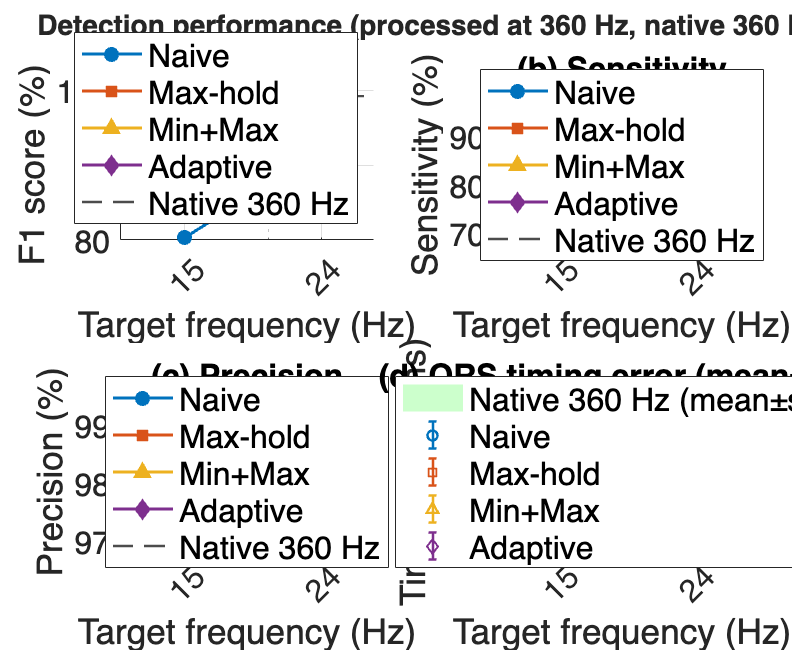

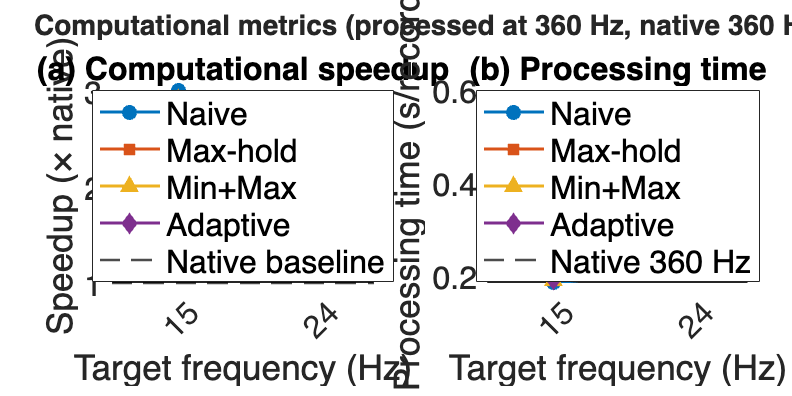

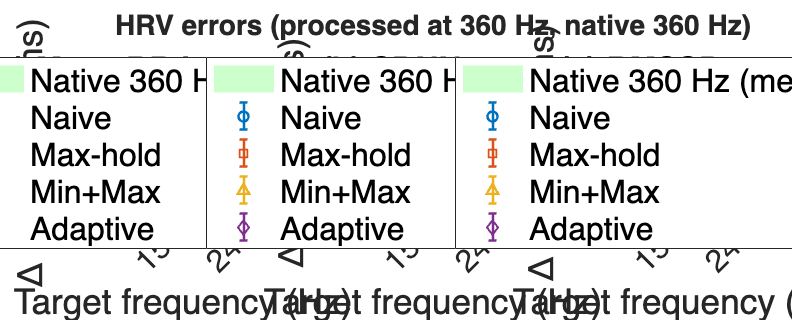

% -------------------------------------------------------------------------
% Plots – split into three figures
% -------------------------------------------------------------------------
freqs_raw = [results.Fs_target];   % e.g., [120,80,60,48,40,30,24,20,16]
% Sort ascending for logical order on log axis
[freqs, idx_sorted] = sort(freqs_raw);
nFreq = length(freqs);

methodNames = {'Naive', 'Max-hold', 'Min+Max', 'Adaptive'};
% RGB triplets (compatible with all MATLAB versions)
colors = {[0, 0.4470, 0.7410], [0.8500, 0.3250, 0.0980], ...
    [0.9290, 0.6940, 0.1250], [0.4940, 0.1840, 0.5560]};
markers = {'o', 's', '^', 'd'};
lineStyles = {'-', '-', '-', '-'};

% Helper to reorder any Nx4 matrix according to sorted indices
reorder = @(x) x(idx_sorted, :);

% Extract and reorder all metric arrays
F1 = reorder(cell2mat(arrayfun(@(f) [f.naive.F1, f.maxhold.F1, f.intel.F1, f.adapt.F1], results, 'UniformOutput', false)'));
Sens = reorder(cell2mat(arrayfun(@(f) [f.naive.Sens, f.maxhold.Sens, f.intel.Sens, f.adapt.Sens], results, 'UniformOutput', false)'));
Prec = reorder(cell2mat(arrayfun(@(f) [f.naive.Prec, f.maxhold.Prec, f.intel.Prec, f.adapt.Prec], results, 'UniformOutput', false)'));
ErrMean = reorder(cell2mat(arrayfun(@(f) [f.naive.ErrMean, f.maxhold.ErrMean, f.intel.ErrMean, f.adapt.ErrMean], results, 'UniformOutput', false)'));
ErrStd = reorder(cell2mat(arrayfun(@(f) [f.naive.ErrStd, f.maxhold.ErrStd, f.intel.ErrStd, f.adapt.ErrStd], results, 'UniformOutput', false)'));
Time = reorder(cell2mat(arrayfun(@(f) [f.naive.Time, f.maxhold.Time, f.intel.Time, f.adapt.Time], results, 'UniformOutput', false)'));
HRV_MeanRR = reorder(cell2mat(arrayfun(@(f) [f.naive.HRV_MeanRR, f.maxhold.HRV_MeanRR, f.intel.HRV_MeanRR, f.adapt.HRV_MeanRR], results, 'UniformOutput', false)'));
HRV_MeanRR_std = reorder(cell2mat(arrayfun(@(f) [f.naive.HRV_MeanRR_std, f.maxhold.HRV_MeanRR_std, f.intel.HRV_MeanRR_std, f.adapt.HRV_MeanRR_std], results, 'UniformOutput', false)'));
HRV_SDNN = reorder(cell2mat(arrayfun(@(f) [f.naive.HRV_SDNN, f.maxhold.HRV_SDNN, f.intel.HRV_SDNN, f.adapt.HRV_SDNN], results, 'UniformOutput', false)'));
HRV_SDNN_std = reorder(cell2mat(arrayfun(@(f) [f.naive.HRV_SDNN_std, f.maxhold.HRV_SDNN_std, f.intel.HRV_SDNN_std, f.adapt.HRV_SDNN_std], results, 'UniformOutput', false)'));
HRV_RMSSD = reorder(cell2mat(arrayfun(@(f) [f.naive.HRV_RMSSD, f.maxhold.HRV_RMSSD, f.intel.HRV_RMSSD, f.adapt.HRV_RMSSD], results, 'UniformOutput', false)'));
HRV_RMSSD_std = reorder(cell2mat(arrayfun(@(f) [f.naive.HRV_RMSSD_std, f.maxhold.HRV_RMSSD_std, f.intel.HRV_RMSSD_std, f.adapt.HRV_RMSSD_std], results, 'UniformOutput', false)'));

% Speedup
Speedup = zeros(nFreq,4);
for m = 1:4
    Speedup(:,m) = avg_time_orig ./ Time(:,m);
end

% Native baselines (already computed earlier in script)
orig_hrv_meanRR = mean(orig_RR_err);
orig_hrv_stdRR  = std(orig_RR_err);
orig_hrv_meanSDNN = mean(orig_SDNN_err);
orig_hrv_stdSDNN  = std(orig_SDNN_err);
orig_hrv_meanRMSSD = mean(orig_RMSSD_err);
orig_hrv_stdRMSSD  = std(orig_RMSSD_err);

native_err_mean = err_orig_mean;
native_err_std  = err_orig_std;

% Offsets in log10 space – uniform spacing on log axis
% Choose small values so points don't overlap visually
log_offsets = [-0.01, -0.005, 0.005, 0.01];  % corresponds to method order
% Compute shifted frequencies: 10^(log10(f) + offset)
freqs_log = log10(freqs);
shifted_freqs = 10.^(freqs_log + log_offsets');  % size: 4 x nFreq (rows=methods, cols=freqs)
% Common settings


xticks_vals = freqs;
xtick_labels = arrayfun(@(x) sprintf('%d', round(x)), xticks_vals, 'UniformOutput', false);
if length(xticks_vals) > 8
    tick_step = 1;   % adjust if needed (e.g., 2)
    xticks_vals = xticks_vals(1:tick_step:end);
    xtick_labels = xtick_labels(1:tick_step:end);
end

% Anonymous function to apply x‑axis properties
setXAxis = @(ax) set(ax, 'XScale', 'log', 'XTick', xticks_vals, ...
    'XTickLabel', xtick_labels, 'XTickLabelRotation', 45, ...
    'XMinorTick', 'off', 'XLim', [min(freqs)*0.8, max(freqs)*1.2]);

% -------------------------------------------------------------------------
% FIGURE 1: Detection metrics (2x2)
% -------------------------------------------------------------------------
fig1 = figure('Position', [100, 100, 1200, 1000], 'Color', 'white');
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% (a) F1 score
ax1 = nexttile;
hold on;
for m = 1:4
    semilogx(ax1, freqs, F1(:,m), 'Color', colors{m}, 'LineStyle', lineStyles{m}, ...
        'LineWidth', 1.5, 'Marker', markers{m}, 'MarkerSize', 6, ...
        'MarkerFaceColor', colors{m}, 'DisplayName', methodNames{m});
end
yline(ax1, f1_orig, 'k--', 'LineWidth', 1.2, 'DisplayName', sprintf('Native %d Hz', Fs_orig_native));
xlabel(ax1, 'Target frequency (Hz)');
ylabel(ax1, 'F1 score (%)');
title(ax1, '(a) F1 score');
grid(ax1, 'on');
setXAxis(ax1);
legend(ax1, 'Location', 'southeast', 'FontSize', 8);
hold off;

% (b) Sensitivity
ax2 = nexttile;
hold on;
for m = 1:4
    semilogx(ax2, freqs, Sens(:,m), 'Color', colors{m}, 'LineStyle', lineStyles{m}, ...
        'LineWidth', 1.5, 'Marker', markers{m}, 'MarkerSize', 6, ...
        'MarkerFaceColor', colors{m}, 'DisplayName', methodNames{m});
end
yline(ax2, sens_orig, 'k--', 'LineWidth', 1.2, 'DisplayName', sprintf('Native %d Hz', Fs_orig_native));
xlabel(ax2, 'Target frequency (Hz)');
ylabel(ax2, 'Sensitivity (%)');
title(ax2, '(b) Sensitivity');
grid(ax2, 'on');
setXAxis(ax2);
legend(ax2, 'Location', 'best', 'FontSize', 8);
hold off;

% (c) Precision
ax3 = nexttile;
hold on;
for m = 1:4
    semilogx(ax3, freqs, Prec(:,m), 'Color', colors{m}, 'LineStyle', lineStyles{m}, ...
        'LineWidth', 1.5, 'Marker', markers{m}, 'MarkerSize', 6, ...
        'MarkerFaceColor', colors{m}, 'DisplayName', methodNames{m});
end
yline(ax3, prec_orig, 'k--', 'LineWidth', 1.2, 'DisplayName', sprintf('Native %d Hz', Fs_orig_native));
xlabel(ax3, 'Target frequency (Hz)');
ylabel(ax3, 'Precision (%)');
title(ax3, '(c) Precision');
grid(ax3, 'on');
setXAxis(ax3);
legend(ax3, 'Location', 'best', 'FontSize', 8);
hold off;

% (d) QRS timing error
ax4 = nexttile;
hold on;
x_patch = [freqs, fliplr(freqs)];
y_patch_err = [ (native_err_mean - native_err_std)*ones(size(freqs)), ...
    fliplr((native_err_mean + native_err_std)*ones(size(freqs))) ];
fill(ax4, x_patch, y_patch_err, 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none', ...
    'DisplayName', sprintf('Native %d Hz (mean±std)', Fs_orig_native));
for m = 1:4
    errorbar(ax4, shifted_freqs(m,:), ErrMean(:,m), ErrStd(:,m), 'Color', colors{m}, ...
        'LineStyle', 'none', 'LineWidth', 1.2, ...
        'Marker', markers{m}, 'MarkerSize', 5, 'CapSize', 4, ...
        'DisplayName', methodNames{m});
end
yline(ax4, 0, 'k:', 'LineWidth', 1, 'HandleVisibility', 'off');
xlabel(ax4, 'Target frequency (Hz)');
ylabel(ax4, 'Timing error (ms)');
title(ax4, '(d) QRS timing error (mean±std)');
grid(ax4, 'on');
setXAxis(ax4);
legend(ax4, 'Location', 'best', 'FontSize', 7);
hold off;

% Figure 1 title
sgtitle(fig1, sprintf('Detection performance (processed at %d Hz, native %d Hz)', Fs_orig, Fs_orig_native), ...
    'FontSize', 14, 'FontWeight', 'bold');

% -------------------------------------------------------------------------
% FIGURE 2: Computational metrics (1x2)
% -------------------------------------------------------------------------
fig2 = figure('Position', [150, 150, 1000, 500], 'Color', 'white');
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% (e) Speedup
ax5 = nexttile;
hold on;
for m = 1:4
    semilogx(ax5, freqs, Speedup(:,m), 'Color', colors{m}, 'LineStyle', lineStyles{m}, ...
        'LineWidth', 1.5, 'Marker', markers{m}, 'MarkerSize', 6, ...
        'MarkerFaceColor', colors{m}, 'DisplayName', methodNames{m});
end
yline(ax5, 1, 'k--', 'LineWidth', 1.2, 'DisplayName', 'Native baseline');
xlabel(ax5, 'Target frequency (Hz)');
ylabel(ax5, 'Speedup (× native)');
title(ax5, '(a) Computational speedup');
grid(ax5, 'on');
setXAxis(ax5);
legend(ax5, 'Location', 'best', 'FontSize', 8);
hold off;

% (f) Processing time
ax6 = nexttile;
hold on;
for m = 1:4
    semilogx(ax6, freqs, Time(:,m), 'Color', colors{m}, 'LineStyle', lineStyles{m}, ...
        'LineWidth', 1.5, 'Marker', markers{m}, 'MarkerSize', 6, ...
        'MarkerFaceColor', colors{m}, 'DisplayName', methodNames{m});
end
yline(ax6, avg_time_orig, 'k--', 'LineWidth', 1.2, 'DisplayName', sprintf('Native %d Hz', Fs_orig_native));
xlabel(ax6, 'Target frequency (Hz)');
ylabel(ax6, 'Processing time (s/record)');
title(ax6, '(b) Processing time');
grid(ax6, 'on');
setXAxis(ax6);
legend(ax6, 'Location', 'best', 'FontSize', 8);
hold off;

% Figure 2 title
sgtitle(fig2, sprintf('Computational metrics (processed at %d Hz, native %d Hz)', Fs_orig, Fs_orig_native), ...
    'FontSize', 14, 'FontWeight', 'bold');

% -------------------------------------------------------------------------
% FIGURE 3: HRV errors (1x3)
% -------------------------------------------------------------------------
fig3 = figure('Position', [200, 200, 1200, 500], 'Color', 'white');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

% (g) ΔMeanRR
ax7 = nexttile;
hold on;
y_patch_hrv1 = [ (orig_hrv_meanRR - orig_hrv_stdRR)*ones(size(freqs)), ...
    fliplr((orig_hrv_meanRR + orig_hrv_stdRR)*ones(size(freqs))) ];
fill(ax7, x_patch, y_patch_hrv1, 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none', ...
    'DisplayName', sprintf('Native %d Hz (mean±std)', Fs_orig_native));
for m = 1:4
    errorbar(ax7, shifted_freqs(m,:), HRV_MeanRR(:,m), HRV_MeanRR_std(:,m), 'Color', colors{m}, ...
        'LineStyle', 'none', 'LineWidth', 1.2, ...
        'Marker', markers{m}, 'MarkerSize', 5, 'CapSize', 4, ...
        'DisplayName', methodNames{m});
end
yline(ax7, orig_hrv_meanRR, 'g--', 'LineWidth', 1.5, 'HandleVisibility', 'off');
xlabel(ax7, 'Target frequency (Hz)');
ylabel(ax7, '\Delta MeanRR (ms)');
title(ax7, '(a) Mean RR interval error');
grid(ax7, 'on');
setXAxis(ax7);
legend(ax7, 'Location', 'best', 'FontSize', 7);
hold off;

% (h) ΔSDNN
ax8 = nexttile;
hold on;
y_patch_hrv2 = [ (orig_hrv_meanSDNN - orig_hrv_stdSDNN)*ones(size(freqs)), ...
    fliplr((orig_hrv_meanSDNN + orig_hrv_stdSDNN)*ones(size(freqs))) ];
fill(ax8, x_patch, y_patch_hrv2, 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none', ...
    'DisplayName', sprintf('Native %d Hz (mean±std)', Fs_orig_native));
for m = 1:4
    errorbar(ax8, shifted_freqs(m,:), HRV_SDNN(:,m), HRV_SDNN_std(:,m), 'Color', colors{m}, ...
        'LineStyle', 'none', 'LineWidth', 1.2, ...
        'Marker', markers{m}, 'MarkerSize', 5, 'CapSize', 4, ...
        'DisplayName', methodNames{m});
end
yline(ax8, orig_hrv_meanSDNN, 'g--', 'LineWidth', 1.5, 'HandleVisibility', 'off');
xlabel(ax8, 'Target frequency (Hz)');
ylabel(ax8, '\Delta SDNN (ms)');
title(ax8, '(b) SDNN error');
grid(ax8, 'on');
setXAxis(ax8);
legend(ax8, 'Location', 'best', 'FontSize', 7);
hold off;

% (i) ΔRMSSD
ax9 = nexttile;
hold on;
y_patch_hrv3 = [ (orig_hrv_meanRMSSD - orig_hrv_stdRMSSD)*ones(size(freqs)), ...
    fliplr((orig_hrv_meanRMSSD + orig_hrv_stdRMSSD)*ones(size(freqs))) ];
fill(ax9, x_patch, y_patch_hrv3, 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none', ...
    'DisplayName', sprintf('Native %d Hz (mean±std)', Fs_orig_native));
for m = 1:4
    errorbar(ax9, shifted_freqs(m,:), HRV_RMSSD(:,m), HRV_RMSSD_std(:,m), 'Color', colors{m}, ...
        'LineStyle', 'none', 'LineWidth', 1.2, ...
        'Marker', markers{m}, 'MarkerSize', 5, 'CapSize', 4, ...
        'DisplayName', methodNames{m});
end
yline(ax9, orig_hrv_meanRMSSD, 'g--', 'LineWidth', 1.5, 'HandleVisibility', 'off');
xlabel(ax9, 'Target frequency (Hz)');
ylabel(ax9, '\Delta RMSSD (ms)');
title(ax9, '(c) RMSSD error');
grid(ax9, 'on');
setXAxis(ax9);
legend(ax9, 'Location', 'best', 'FontSize', 7);
hold off;

% Figure 3 title
sgtitle(fig3, sprintf('HRV errors (processed at %d Hz, native %d Hz)', Fs_orig, Fs_orig_native), ...
    'FontSize', 14, 'FontWeight', 'bold');

% -------------------------------------------------------------------------
% Uniform font size adjustment for all three figures
% -------------------------------------------------------------------------
allFigs = [fig1, fig2, fig3];
AXIS_LABEL_FS = 16;
TICK_LABEL_FS = 16;
TITLE_FS = 16;
LEGEND_FS = 16;

for f = allFigs
    allAxes = findall(f, 'Type', 'axes');
    for ax = allAxes'
        ax.XLabel.FontSize = AXIS_LABEL_FS;
        ax.YLabel.FontSize = AXIS_LABEL_FS;
        ax.XAxis.FontSize = TICK_LABEL_FS;
        ax.YAxis.FontSize = TICK_LABEL_FS;
        ax.Title.FontSize = TITLE_FS;
    end
    allLegends = findall(f, 'Type', 'legend');
    for leg = allLegends'
        leg.FontSize = LEGEND_FS;
    end
end

% -------------------------------------------------------------------------
% Save figures
% -------------------------------------------------------------------------
if strcmp(database, 'mitdb')
    db_name = 'mitdb';
elseif strcmp(database, 'qtdb')
    db_name = 'qtdb';
elseif strcmp(database, 'nstdb')
    db_name = 'nstdb';
else
    db_name = database;
end

% Figure 1: detection
% exportgraphics(fig1, sprintf('detection_performance_%s.png', db_name), 'Resolution', 300);
% exportgraphics(fig1, sprintf('detection_performance_%s.pdf', db_name), 'ContentType', 'vector');
% % Figure 2: computational
% exportgraphics(fig2, sprintf('computational_metrics_%s.png', db_name), 'Resolution', 300);
% exportgraphics(fig2, sprintf('computational_metrics_%s.pdf', db_name), 'ContentType', 'vector');
% % Figure 3: HRV
% exportgraphics(fig3, sprintf('hrv_errors_%s.png', db_name), 'Resolution', 300);
% exportgraphics(fig3, sprintf('hrv_errors_%s.pdf', db_name), 'ContentType', 'vector');

fprintf('Figures saved:\n');

Figures saved:


fprintf('  Detection: detection_performance_%s.[png|pdf]\n', db_name);

  Detection: detection_performance_mitdb.[png|pdf]


fprintf('  Computational: computational_metrics_%s.[png|pdf]\n', db_name);

  Computational: computational_metrics_mitdb.[png|pdf]


fprintf('  HRV: hrv_errors_%s.[png|pdf]\n', db_name);

  HRV: hrv_errors_mitdb.[png|pdf]



% =========================================================================
% Helper functions
% =========================================================================
function [TP, FP, FN, errors_ms] = match_detections_with_errors(detected, gt, tol, Fs)
    detected = double(detected(:));
    gt = double(gt(:));
    TP = 0; FP = 0; FN = 0;
    matched_gt = false(size(gt));
    matched_det = false(size(detected));
    errors_samples = [];
    for i = 1:length(detected)
        d = detected(i);
        idx = find(abs(gt - d) <= tol);
        for j = idx'
            if ~matched_gt(j) && ~matched_det(i)
                TP = TP + 1;
                matched_gt(j) = true;
                matched_det(i) = true;
                errors_samples = [errors_samples; d - gt(j)];
                break;
            end
        end
    end
    FP = sum(~matched_det);
    FN = sum(~matched_gt);
    errors_ms = errors_samples / Fs * 1000;
    end
    
    function det_orig = map_detections_to_original(det_pt, sparse_time, sparse_idx, Fs_det, ~)
    det_pt = double(det_pt(:));
    det_times = (det_pt - 1) / Fs_det;
    min_t = min(sparse_time);
    max_t = max(sparse_time);
    det_times = max(min(det_times, max_t), min_t);
    nearest_idx = interp1(sparse_time, 1:length(sparse_time), det_times, 'nearest');
    nearest_idx = round(nearest_idx);
    det_orig = sparse_idx(nearest_idx);
    det_orig = sort(double(det_orig(:)));
    end
    
    function [err_meanRR, err_SDNN, err_RMSSD] = compute_hrv_errors(det, gt, Fs, tol)
    det = double(det(:));
    gt = double(gt(:));
    used_gt = false(length(gt),1);
    matched_det = [];
    matched_gt = [];
    for i = 1:length(det)
        d = det(i);
        dist = abs(gt - d);
        [minDist, idx] = min(dist);
        if minDist <= tol && ~used_gt(idx)
            matched_det(end+1) = d;
            matched_gt(end+1) = gt(idx);
            used_gt(idx) = true;
        end
    end
    if length(matched_det) < 3
        err_meanRR = []; err_SDNN = []; err_RMSSD = [];
        return;
    end
    rr_det = diff(matched_det) / Fs * 1000;
    rr_gt  = diff(matched_gt) / Fs * 1000;
    med_det = median(rr_det);
    med_gt = median(rr_gt);
    keep_det = (rr_det >= 0.5*med_det) & (rr_det <= 1.5*med_det);
    keep_gt  = (rr_gt  >= 0.5*med_gt)  & (rr_gt  <= 1.5*med_gt);
    rr_det = rr_det(keep_det);
    rr_gt  = rr_gt(keep_gt);
    if length(rr_det) < 3
        err_meanRR = []; err_SDNN = []; err_RMSSD = [];
        return;
    end
    err_meanRR = mean(rr_det) - mean(rr_gt);
    err_SDNN   = std(rr_det) - std(rr_gt);
    err_RMSSD  = sqrt(mean(diff(rr_det).^2)) - sqrt(mean(diff(rr_gt).^2));
end